# **Repaso**

## Vectores en Matlab

clear; clc;

% Definir Vectores
x = 0:5:100

x =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


x2 = [1 2 3 4]

x2 =      1     2     3     4



% Renglón, Columna
x3 = zeros(1,7) 

x3 =      0     0     0     0     0     0     0


x4 = ones(1,7)

x4 =      1     1     1     1     1     1     1



% Números Aleatorios entre 0 y 1
x5 = rand(1,7) 

x5 =     0.8010    0.0292    0.9289    0.7303    0.4886    0.5785    0.2373



% Linspace (Inicio, Final, N.Elementos)
x6 = linspace(0,10,11)

x6 =      0     1     2     3     4     5     6     7     8     9    10


Operaciones de Matrices o Vectores

A + B

A - B

A * B

A .* B

A / B -> A * inv(B)

A ./ B

A .^ B

Las operaciones con punto significa posición por posición (pero deben tener misma dimensión)

### Ejemplo de División de Matrices

A = [100 200 300; 400 500 600; 160 170 180]

y =      0     1     4     9    16    25    36    49    64    81   100


A =    100   200   300
   400   500   600
   160   170   180


B = [700 800 90; 100 110 120; 130 140 150]

B =    700   800    90
   100   110   120
   130   140   150




C = A * inv(B)

C =     0.0000   40.0000  -30.0000
    0.0000   30.0000  -20.0000
    0.0000   -1.0000    2.0000


C1 = A / B

C1 =          0   40.0000  -30.0000
         0   30.0000  -20.0000
    0.0000   -1.0000    2.0000


C2 = A ./ B

C2 =     0.1429    0.2500    3.3333
    4.0000    4.5455    5.0000
    1.2308    1.2143    1.2000


## Plotteando en R2

clear; clc;
x6 = linspace(0,10,11)

x6 =      0     1     2     3     4     5     6     7     8     9    10


y = x6.^2

y =      0     1     4     9    16    25    36    49    64    81   100


% Plot (x, y, '[COLOR][FORMALÍNEA][FIGURAENTREINTERVALOS]')
% plot(x6, y, 'm-.s')
% 
% % Poner gráficas en mismo lugar
% hold on
% plot(x6, sqrt(x6.^3), ":")
% title("Título")
% xlabel("X")
% ylabel("Y")
% legend("x^2", "sqrt(x^3)")
% grid on % Poner Cuadrícula
% 
% % Segunda Forma de poner en mismo lugar dos gráficas
% plot(x6, y, 'm-.s', x6, sqrt(x6.^3), ":")

## Plottear en R3

clear; clc;
t = 0:pi/50:10*pi;
plot3(sin(t), cos(t), t, "r:")

Se puede usar comet3 para hacer una animación en R3 (También existe en R2)

%comet3(sin(t), cos(t), t)

Las Ecuaciones Paramétricas son aquellas que depende de un parámetro


$$\left\lbrace \begin{array}{ll}
x=t & \\
y=t^2  & 
\end{array}\right.,t\in R$$


### Ejemplo de Paramétricas

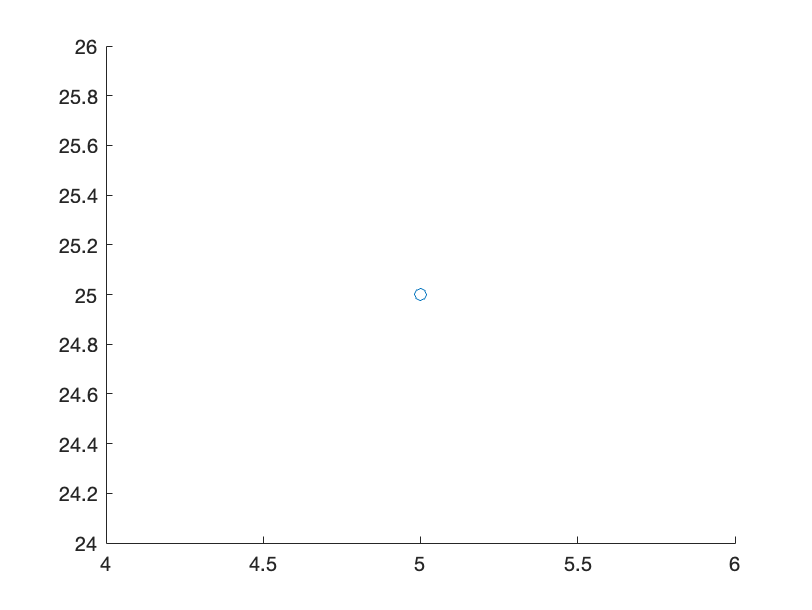

clear; clc;

t = 5:0.1:5;
x = t;
y = t.^2;
comet(x,y) % Gráfica Dinámica

## Actividad del Carro

t = 0:0.04:sqrt(10); % sqrt(10) por el despeje
x = 5*t + 10;
y = 50 - 10*(t.^2 / 2);


yline(0)
xline(0)
hold on

title("Auto al Precipicio")
grid on

comet(x, y)